# PBMRAC Tuning:

This live script covers the tuning of the PBMRAC controller developed in PBMRAC development, using the tools developed in said live script. Actuator limitations in terms of range and rate are considered to guide possible choices for the adaptive gains. The actuators are the main limitations to the system's behaviour. 

addpath("Models and Auxiliary Functions\")

## System Defintion and Initialization: 

System parameters definition: 

%Tune position controller: 
%Performance Goals: 
omega_n_p=1.75; %[rad/s]
zeta_p=0.8;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

%For predictor dynamics: 
A_p=[zeros(3,3),eye(3,3);zeros(3,3),zeros(3,3)];
B_p=[zeros(3,3);eye(3,3)];
B_pT=B_p';

%Define trajectory: 
R_turn_H=5; %[m]
R_turn_V=1.5; %[m]

Initialization of system parameters: 

%Non-Nominal system: 
p_i_0=[0;0;1];
v_i_0=[0;0;0];
a_e_tilde=[0;0;-9.81]; %the actual physical baseline

%Initialize adaptive laws: 
lambda_hat_0=[1;1;1];
a_e_hat_0=a_e_tilde;
omega_a_hat_0=[lambda_hat_0;a_e_hat_0];

%Initialize predictor: 
p_i_hat_0=p_i_0;
v_i_hat_0=v_i_0;
x_hat_0=[p_i_hat_0;v_i_hat_0];


## Tuning with 0.4kg package:

%Define Lambda in this case: 
m_UAV=1.2; %[kg]
m_p=0.4; %[kg]
Lambda_tilde=m_UAV/(m_UAV+m_p)*eye(3,3);

Tune controller:

L=100*eye(6,6);
Gamma_a=20*eye(6,6);

Simulate: 

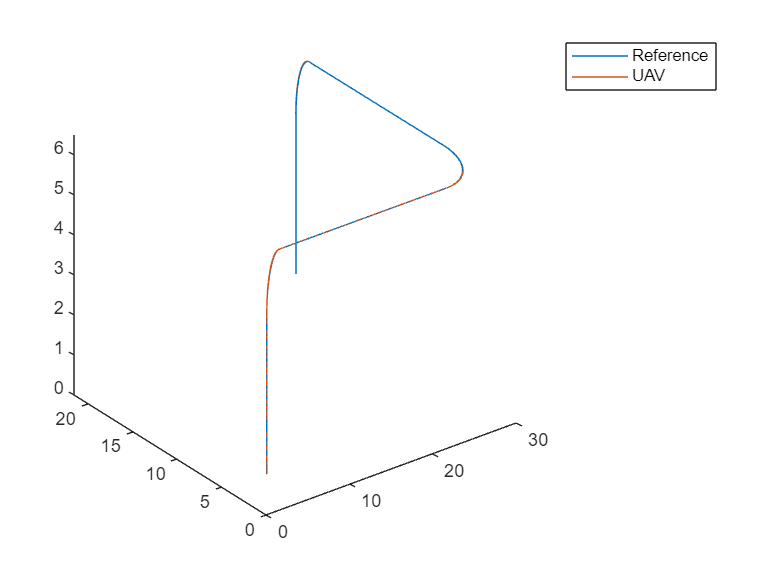

simout=sim("PBMRAC_Tuning_Model.slx","StopTime","25","RelTol","1e-6");
%Plot system response against reference trajectory: 
%System trajectory:
model_trajectory=nan(3,length(simout.p_i.time));

for i=1:length(simout.p_i.time)
    model_trajectory(:,i)=simout.p_i.data(:,1,i);
end

%Plot trajectory:
tv=linspace(0,25,1000);
ref_trajectory=nan(3,length(tv));

for i=1:length(tv)
    [ref_trajectory(:,i),~,~,~]=representative_trajectory(tv(i),R_turn_V,R_turn_H);
end

figure
clf
plot3(ref_trajectory(1,:),ref_trajectory(2,:),ref_trajectory(3,:),'DisplayName','Reference')
hold on
plot3(model_trajectory(1,:),model_trajectory(2,:),model_trajectory(3,:),'DisplayName','UAV')
legend()


T=25; %simulation duration. 

%Evaluate reference trajectory at adequate timesteps:
model_velocity=nan(3,length(simout.v_i.time));
ref_position=nan(3,length(simout.p_i.time));
ref_velocity=nan(3,length(simout.v_i.time));

pos_integrand=nan(1,length(simout.p_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_i.time)
    [ref_position(:,i),~,~,~]=representative_trajectory(simout.p_i.time(i),R_turn_V,R_turn_H);
    pos_integrand(i)=(model_trajectory(:,i)-ref_position(:,i))'*(model_trajectory(:,i)-ref_position(:,i));
end

for i=1:length(simout.v_i.time)
    [~,ref_velocity(:,i),~,~]=representative_trajectory(simout.v_i.time(i),R_turn_V,R_turn_H);
    model_velocity(:,i)=simout.v_i.data(:,1,i);
    vel_integrand(i)=(model_velocity(:,i)-ref_velocity(:,i))'*(model_velocity(:,i)-ref_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.v_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.0277

display(vel_Error)

vel_Error = 0.0279

Let's check actuator limits. For the range limitations, it makes more sense to look at limit accelerations. One can place the actuator limits by dividing the limitations on the thrust's norm and dividing it by the real mass of the system. For rate saturation, we will consider the FFT of the control input in the adaptive phase to see if it's reasonable. 

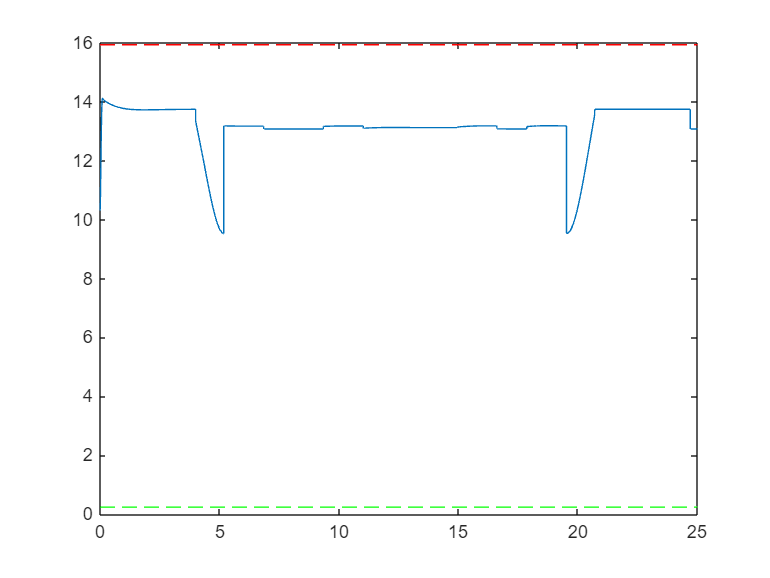

%First, look at how the norm of u evolves over time:
%Reshape dataset: 
u=nan(3,length(simout.u.time));
u_norm=nan(1,length(simout.u.time));
for i=1:length(simout.u.time)
    u(:,i)=simout.u.data(:,1,i);
    u_norm(1,i)=norm(u(:,i));
end

fc_norm_max=4.25*6; %given saturation limits on actuators
u_norm_max=fc_norm_max/(m_UAV+m_p);
fc_norm_min=0.0635*6; %given saturation limits on actuators
u_norm_min=fc_norm_min/(m_UAV+m_p);
figure
clf
plot(simout.u.time',u_norm,'DisplayName','Requested Control Input')
hold on
plot(simout.u.time',u_norm_max*ones(size(simout.u.time')),'r--','DisplayName','Saturation Maximum')
plot(simout.u.time',u_norm_min*ones(size(simout.u.time')),'g--','DisplayName','Saturation Minimum')

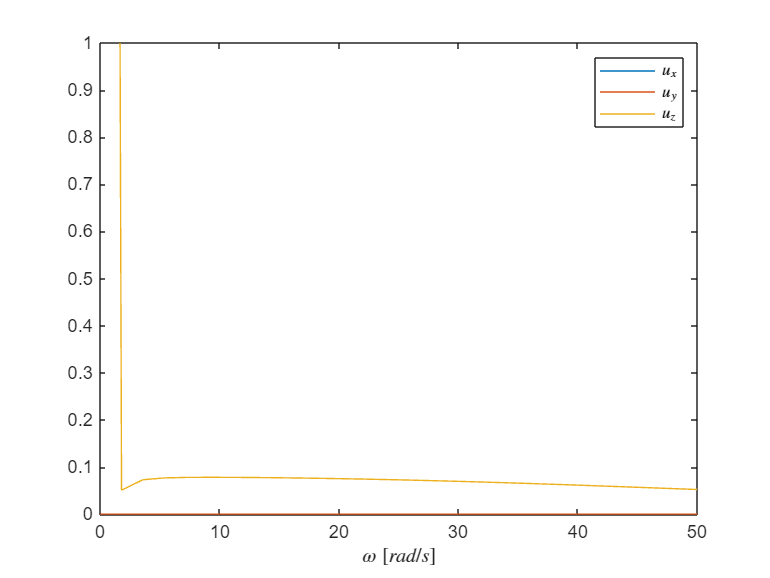

%Then, check FFT of the adaptive phase to analyze frequency content of
%control input signal
%Sampling frequency and data vector: 
Fs=1000; %[Hz]
Ts=3.5;  %[s]
nSamples=Fs*Ts;
dt=1/Fs;
t_Samples=dt*(0:nSamples-1);
fplot=1/Ts*(0:nSamples/2);

figure
clf
for i=1:3
    u_sampled=interp1(simout.u.time',u(i,:),t_Samples,'spline');
    u_fft=fft(u_sampled);
    P2=abs(u_fft/nSamples);
    P1 = P2(1:nSamples/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    plot(2*pi*fplot,P1)
    hold on
end
xlabel('$\omega \; [rad/s]$','Interpreter','latex')
legend('$u_x$','$u_y$','$u_z$','Interpreter','latex')
axis([0 50 0 1])

#### Conclusions: 

L=1 and Gamma_a=1 violates range and rate constraints, but shows great performance. 

L=10 and Gamma_a=1 meets all constraints and provides good performance, but is a bit riskier in terms of range saturation.

 L=100 and Gamma_a=1 meets all constraints but with mediocre performance. It can do with higher Gamma_a.

L=100 and Gamma_a=5 is the best so far! Half the error of the previous case and good margin in terms of range and rate saturation. 

L=100 and Gamma=7.5 is even better than the previous one. 

L=100 and Gamma=10 is the best so far! Great performance, ample range margin and great in terms of range. 

L=100 and Gamma=20 is also looking great, particularly for performance, but might be a bit riskier in terms of rate (still looks like a good proposal though). 

So:

I will consider the adaptive controller preliminarily tuned with L=100 and Gamma_a=20 although, if needed, with Gamma_a=10 and Gamma_a=15 as they also look promising. 